clc
clear
% -----------------------------
% 数据可视化脚本
% -----------------------------

% 选择 .xlsx 文件
[fileName, filePath] = uigetfile('*.xlsx', '选择 .xlsx 文件');
if fileName == 0
    error('未选择文件');
end
fullFilePath = fullfile(filePath, fileName);

% 读取数据
data = readmatrix(fullFilePath);
if isempty(data)
    error(['文件 ', fileName, ' 为空或格式不正确']);
end

[timepoints, n] = size(data);

% 定义每个图显示的最大细胞数量
cellsPerFigure = 10;

% 计算需要绘制的图数量
numFigures = ceil(n / cellsPerFigure);

% 定义轨迹之间的间隔
maxTraceValue = max(data, [], 'all'); % 获取所有轨迹的最大值
spacing = maxTraceValue * 1.2; % 设置间隔为最大值的 120%


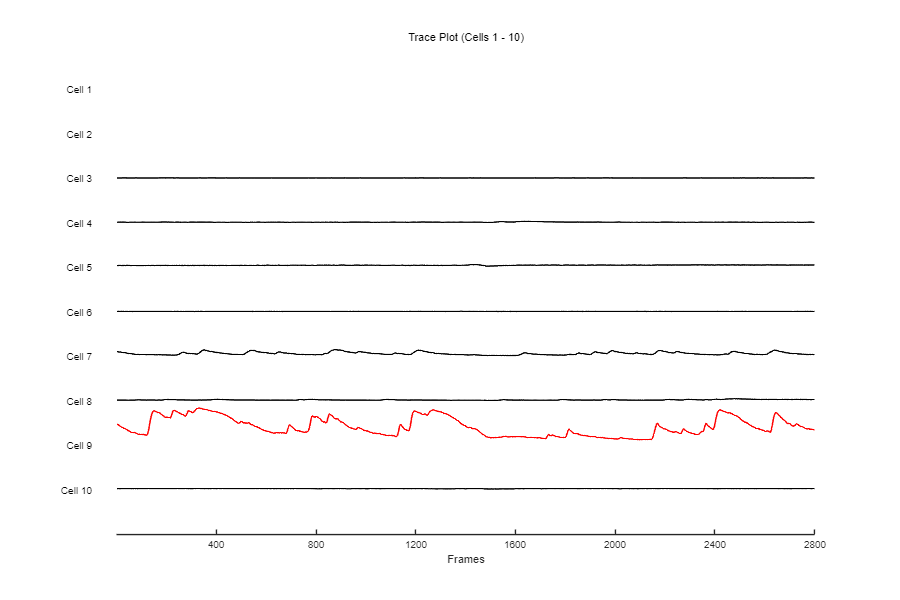

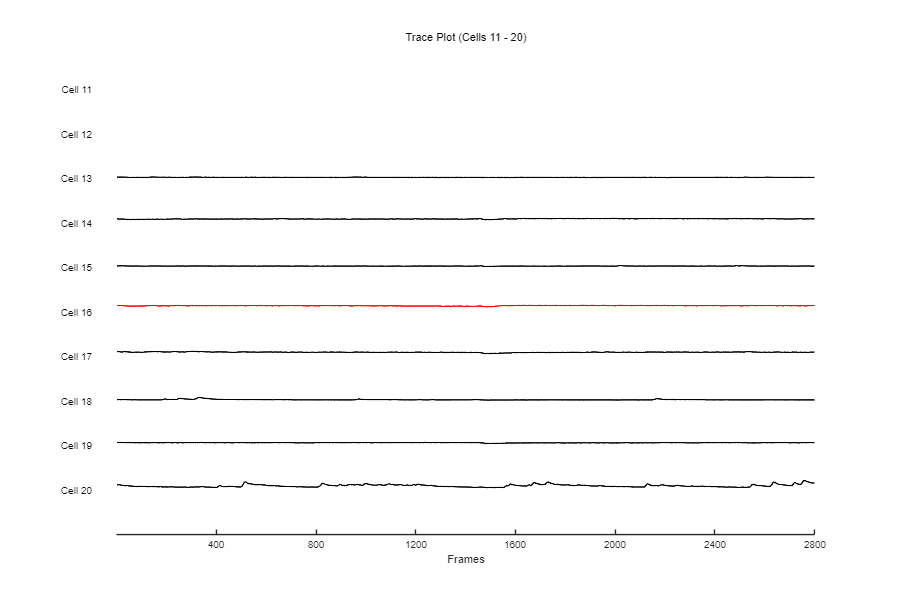

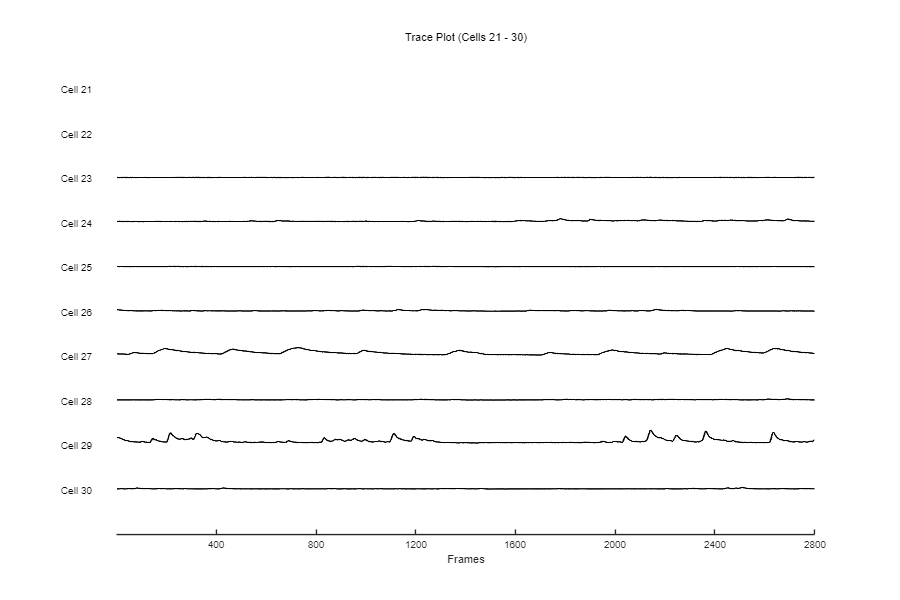

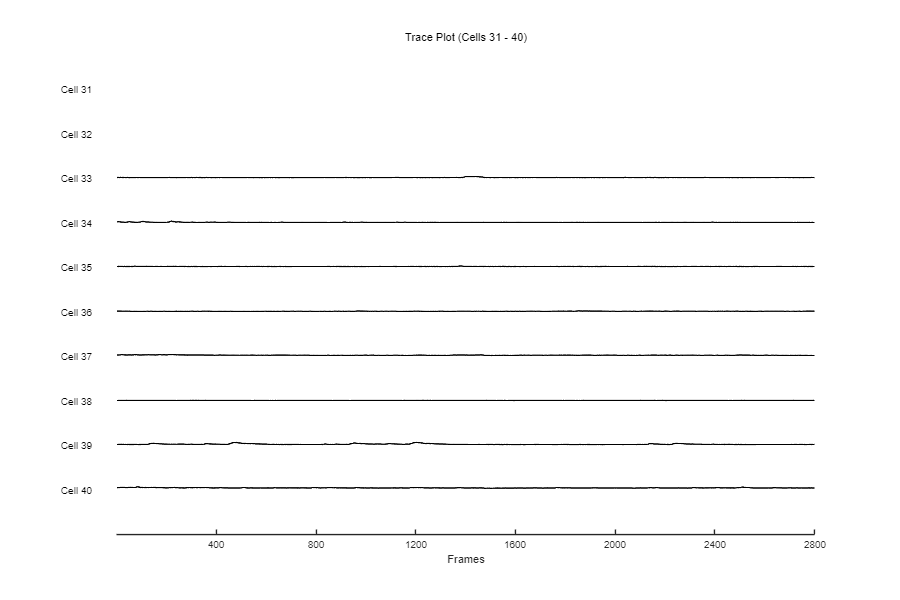

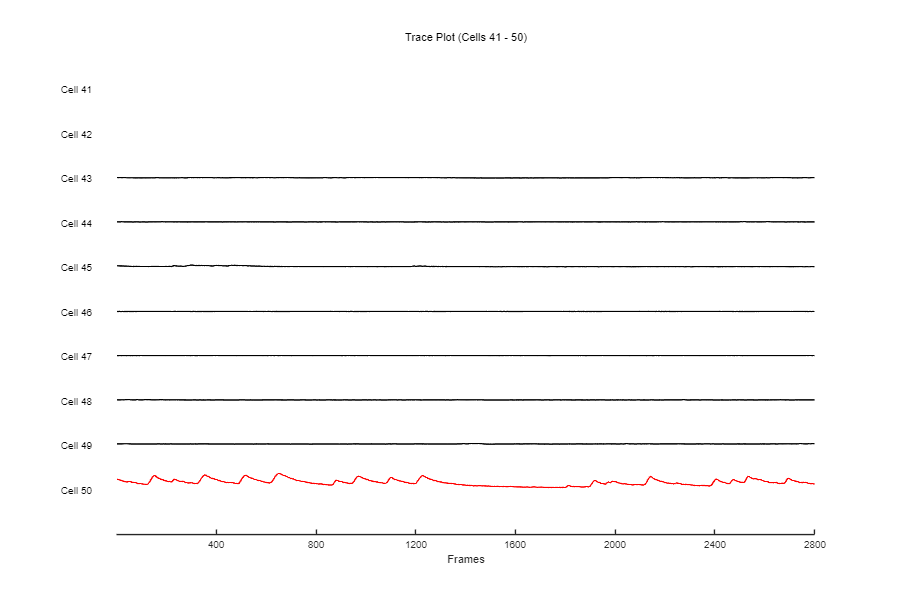

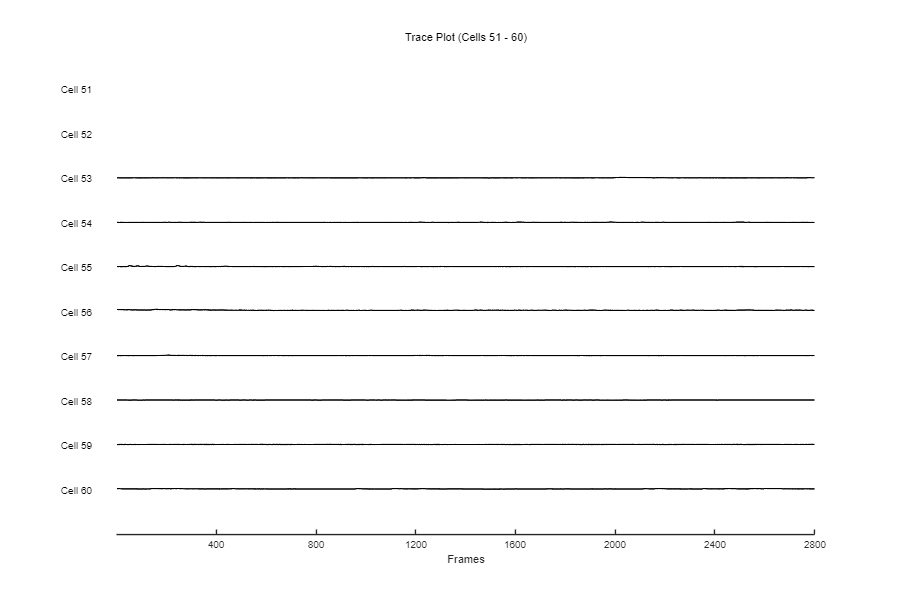

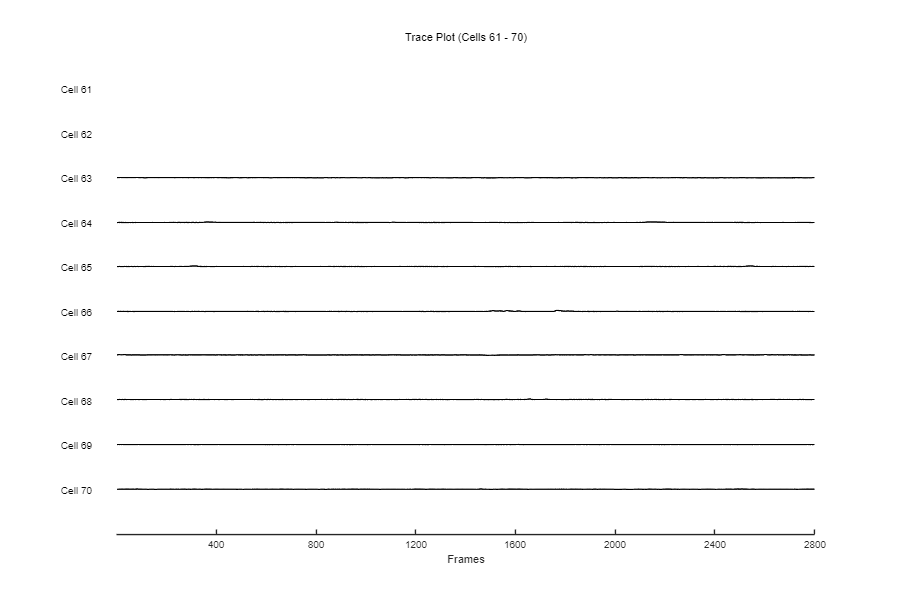

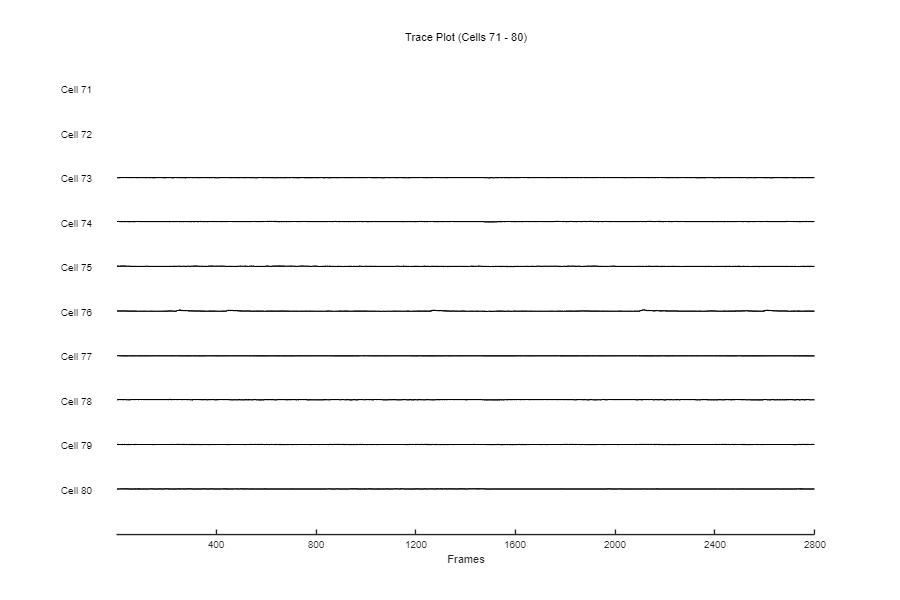


% -----------------------------
% 计算 calcium power
% -----------------------------
% 定义 calcium power 计算公式：积分的绝对值
calciumPower = sum(abs(data), 1);

% 计算整体 calcium power 的标准差和均值
meanPower = mean(calciumPower);
stdPower = std(calciumPower);

% 定义阈值（3 倍标准差）
threshold = meanPower + 2 * stdPower;

% -----------------------------
% 绘图
% -----------------------------
for fig = 1:numFigures
    % 创建新图窗口
    figure('Position', [100, 100, 1200, 800]);
    
    % 确定当前图中要显示的细胞索引
    startCell = (fig - 1) * cellsPerFigure + 1;
    endCell = min(fig * cellsPerFigure, n);
    numCellsToShow = endCell - startCell + 1;
    
    hold on;
    for i = 1:numCellsToShow
        cellIndex = startCell + i - 1;
        traceOffset = (numCellsToShow - i) * spacing; % 轨迹垂直位移

        % 根据 calcium power 判断颜色
        if calciumPower(cellIndex) > threshold
            color = 'r'; % 超过阈值绘制为红色
        else
            color = 'k'; % 正常情况为黑色
        end

        % **绘制轨迹（加粗）**
        plot(data(:, cellIndex) + traceOffset, 'Color', color, 'LineWidth', 1.5);

        % 标注细胞 ID（在轨迹左侧，间隔4个字符）
        text(-100, traceOffset, ['Cell ', num2str(cellIndex)], ...
            'VerticalAlignment', 'middle', 'HorizontalAlignment', 'right');
    end
    
    % 设置坐标轴范围
    ylim([-spacing, spacing * numCellsToShow]);
    
    % **设置 X 轴最大值为 2800，如果数据不足 2800，则自适应**
    if timepoints >= 2800
        xlim([1, 2800]);
    else
        xlim([1, timepoints]);
    end
    
    % **X 轴以 400 为刻度间隔**
    xticks(0:400:2800);
    xlabel('Frames');
    
    % 设置标题
    title(['Trace Plot (Cells ', num2str(startCell), ' - ', num2str(endCell), ')']);
    
    % **去除 Y 轴（包括刻度、标签、线条）**
    set(gca, 'YTick', [], 'YColor', 'none');
    
    hold off;
end


disp('绘图完成！');

绘图完成！
